# Training the classifier & confidence-based review

In this file we demonstrate how to train the classifier, generate predictions, launch the confidence-based review, and export the project results. We do so as a continuation of the example in the $\texttt{demo\_project\_1.mlx}$ script. In that project, we demonstrated how to create a project, import video, extract its frames and features, and launch the annotator, and we did so using a demonstration project with a small number of short, video without annotations. Here, we provide annotations and already extracted features corresponding to the full-length videos in the home-cage dataset, and use these annotations to run steps 6-11 of the project workflow (see below).

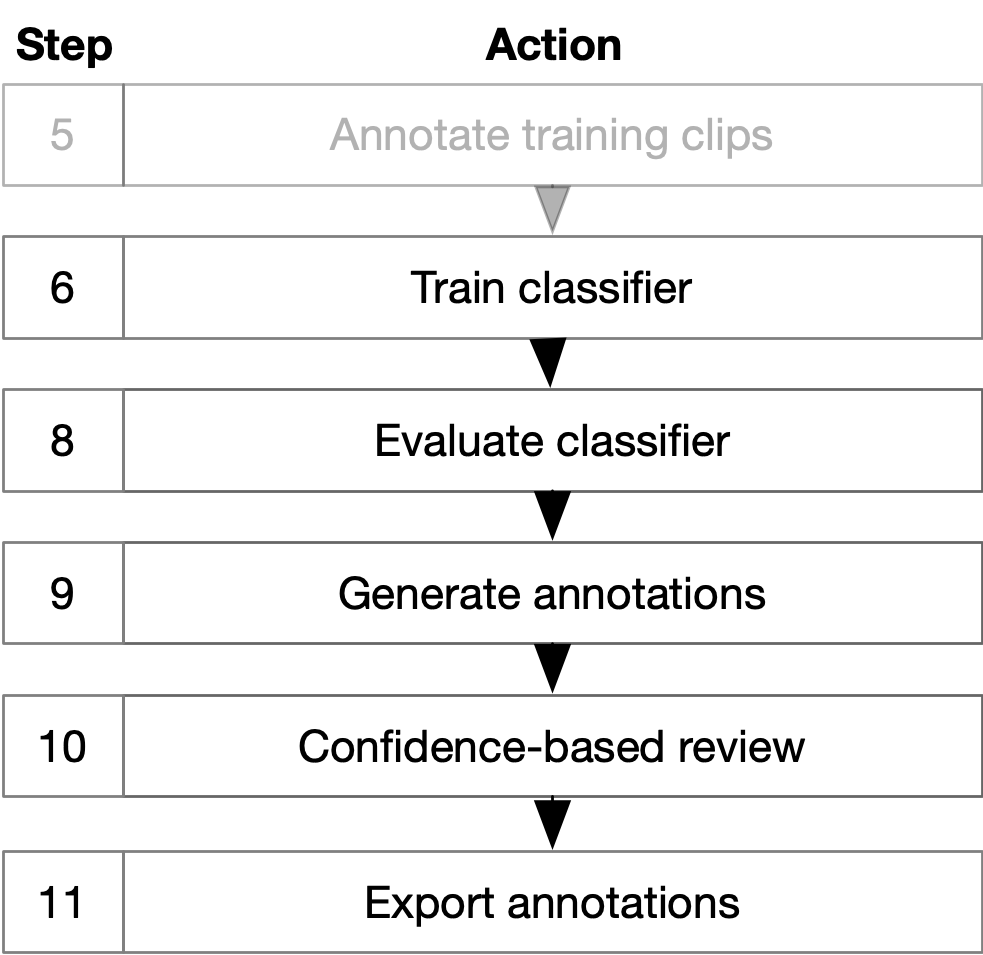

## Downloading the example project

Download the folder for project_2 using the link [here](https://drive.google.com/drive/folders/1jE6OKFNRZqhdqCmZ_--5uEfTUMBtxRnF?usp=sharing). This contains the example project used in this script.

## Loading/generating the clip table

After the video features have been generated and a subset of the video annotated (the former we expedite by using the downloaded features, and the latter by using the dataset labels), we are ready to train the classifier. To do so, we first contruct a DeepAction project by passing the folder where our project is stored to the $\texttt{DeepActionProject}$ class.

projectFolder = '/Users/harriscaw/Documents/Behavior classification/Projects/project_2'; % Change this to the desired project path on your computer
project = DeepActionProject(projectFolder);

We then get the annotations/features available to train the classifier using the following command:

project = project.GetClassifierData();

Then because almost all of the video has been annotated, we can artifically mark some of the clips as incomplete using the helper function below.

nClips = 50; % Number of clips to mark as incomplete
project = MarkClipsAsIncomplete(project, nClips);

## Splitting into train/validation/test/unlabeled sets

After we have generated clips for the project, we select clips for use in training, validation, and testing. The training clips will be used directly to train the classifier. The validation clips will be used to tune the classifier training and train the confidence scorer. And the test clips will be used to evaluate both the classifier and the confidence scorer prior to the confidence-based review. 

The proportion of labeled data in each of these sets is specified in the $\texttt{[Evaluation]}$ section of the $\texttt{config.txt}$ file. The $\texttt{TrainProportion}$, $\texttt{ValidationProportion}$, and $\texttt{TestProportion}$ parameters govern the proportion of clips in each set. By default, 60 percent of data is used in training, and 20 percent in validation and testing.

To generate these sets, we run the $\texttt{SplitClipData}$ method on our project:

project = project.SplitClipData();

## Setting up the classifier

After the clip data have been split into sets, we create the classifier to use in training. To do so, we first specify the sequence-to-sequence LSTM via the parameters in the $\texttt{[Classifier]}$ section of the configuration file. We also specify the length of the sequences to further divide the clips into. The full set of training parameters is specified in the $\texttt{config.md}$ file.

project = project.SetUpClassifier('showplots', true);

## Training the classifier

After preparing the classifier, the command $\texttt{TrainClassifier}$ is used to train the recurrent neural network, evaluate its performance (results output to the $\texttt{./results}$ folder of the project), and generate predictions for un-annotated clips. 

project = project.TrainClassifier();

## Training the confidence-based review

The command $\texttt{GenerateConfidenceScores}$ is then used to generate confidence scores for the clips.

project = project.GenerateConfidenceScores();

## Running the confidence-based review

Clips can then be reviewed using the annotator. 

project = project.LaunchAnnotator()

## Final checks & data export

This command outputs a set of clips to the $\texttt{./results/labeled\_clips}$ folder with behavior labels overlaid. Use the parameter $\texttt{PlaybackSpeed}$ to control the output video speed.

project.CreateLabeledClips('PlaybackSpeed', 3)

Full annotations for each video can then be exported using the $\texttt{ExportAnnotations}$ function, which outputs annotations as $\texttt{.csv}$ files to the $\texttt{./results}$ folder.

project.ExportAnnotations()